close all; clear; clc;
dbstop if error;

fname = fullfile('data','robot_arm.dat');
disp('Loading data...') 

Loading data...


data = load(fname);
u = data(:,1); y = data(:,2); t = (1:length(u))';
sf = 2;  % split factor
ut = u(1:end*(1-1/sf)); yt = y(1:end*(1-1/sf)); tt = t(1:end*(1-1/sf));
uv = u(end*(1-1/sf)+1:end); yv = y(end*(1-1/sf)+1:end); tv = t(end*(1-1/sf)+1:end);
clear fname;

% % Understanding data
disp('Understanding the data')

Understanding the data


disp('Plotting the input and the output signals...')

Plotting the input and the output signals...


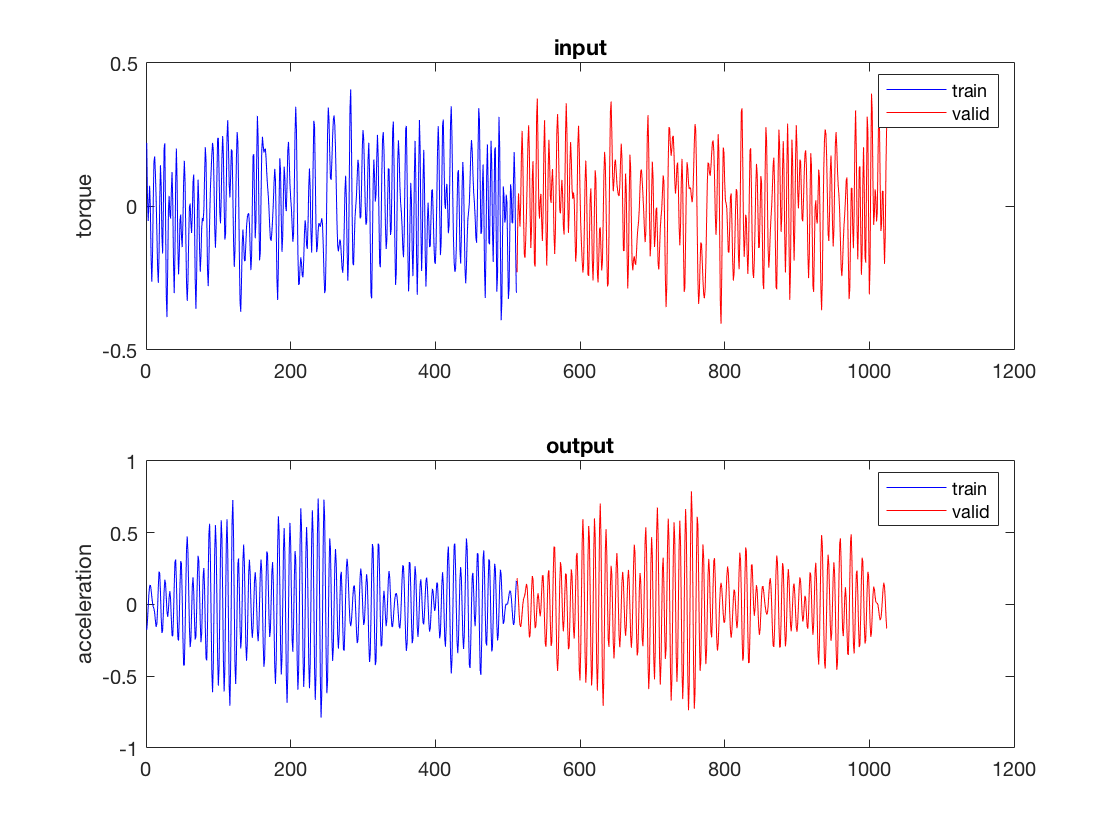

figure
subplot(2,1,1); plot(tt, ut, 'b'); hold on; plot(tv,uv,'r'); 
ylabel('torque'); title('input'); legend('train','valid');
subplot(2,1,2); plot(tt, yt, 'b'); hold on; plot(tv, yv,'r'); 
ylabel('acceleration');title('output'); legend('train','valid');

% pause

disp('Plotting the Empirical Transfer Function Estimate of training and validation data...')

Plotting the Empirical Transfer Function Estimate of training and validation data...


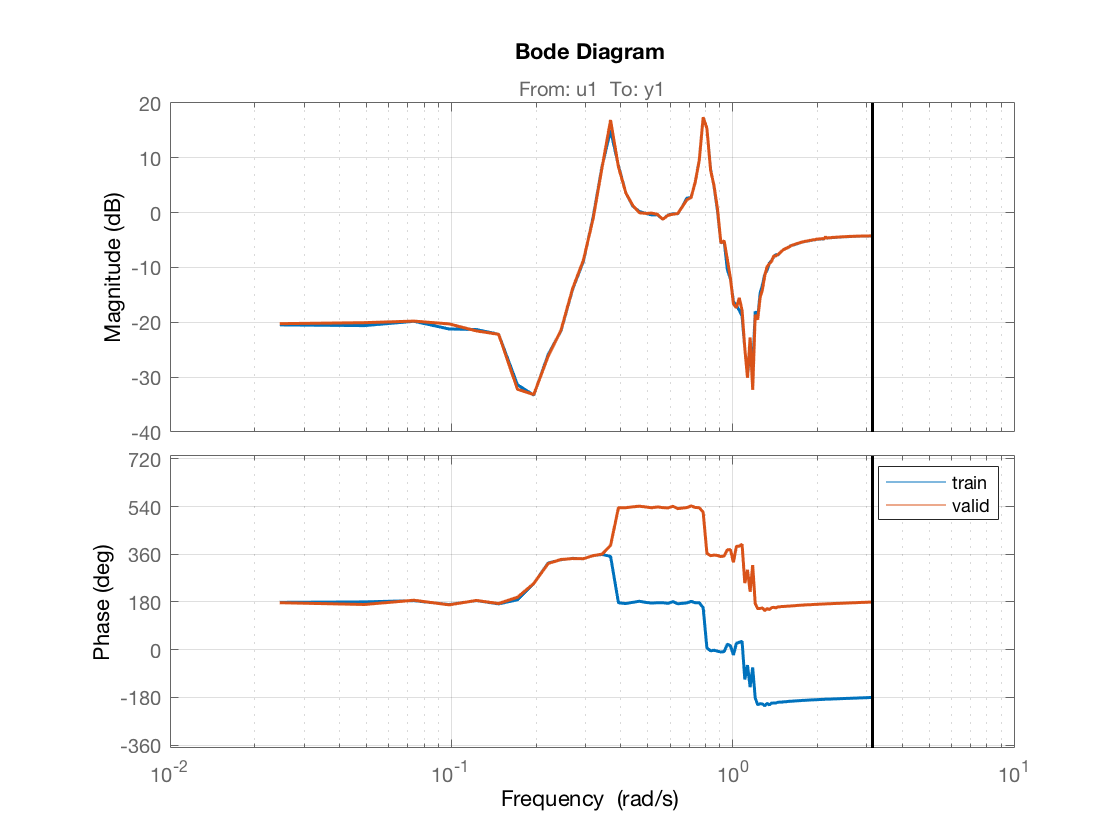

Ts = 1;  % I dont know about this value!
zt = iddata(yt, ut, Ts);  % training data
zv = iddata(yv, uv, Ts);  % validation data
tr = getTrend(zt);
zt = detrend(zt, tr);

ge_t = etfe(zt);
ge_v = etfe(zv);
figure; 
bode(ge_t, ge_v); legend('train','valid'); grid on;
set(findall(gcf,'type','line'),'linewidth',1.5)


% Here we show the bode plot of empirical transfer function estimate.
% Because the input signal is periodic, the estimate is unbiased.

% By examining the bode plot, we can have an initial guess of the number of poles and zeros
% we can observe that there are four sharp corners,
% each of which represent two conjugate poles or two conjugate zeros depending on 
% its concave or convex. The first and last parts
% of the amplitude plot are ladder-shaped, which means that there are two
% more real poles. And we can also see that there is one hollow between two spikes, 
% which represent a zero. Thus, there are six poles and five zeros in total.

% pause

% auto- and cross-correlation
%correlations(u, y)

%% Model fitting
model_handles = {@arx, @oe, @n4sid, @ssest, @tfest};
k = 5;
[models, mses, ~, akaikePre, akaikeIC] = modelOrderVsFreeParams(model_handles, zt, zv, 10, k);

Model order 1 for arx
Model order 1 for oe
Model order 1 for n4sid
Model order 1 for ssest
Model order 1 for tfest
Model order 2 for arx
Model order 2 for oe
Model order 2 for n4sid
Model order 2 for ssest
Model order 2 for tfest
Model order 3 for arx
Model order 3 for oe
Model order 3 for n4sid
Model order 3 for ssest
Model order 3 for tfest
Model order 4 for arx
Model order 4 for oe
Model order 4 for n4sid
Model order 4 for ssest
Model order 4 for tfest
Model order 5 for arx
Model order 5 for oe
Model order 5 for n4sid
Model order 5 for ssest
Model order 5 for tfest
Model order 6 for arx
Model order 6 for oe
Model order 6 for n4sid
Model order 6 for ssest
Model order 6 for tfest
Model order 7 for arx
Model order 7 for oe
Model order 7 for n4sid
Model order 7 for ssest
Model order 7 for tfest
Model order 8 for arx
Model order 8 for oe
Model order 8 for n4sid
Model order 8 for ssest
Model order 8 for tfest
Model order 9 for arx
Model order 9 for oe
Model order 9 for n4sid
Model order 9

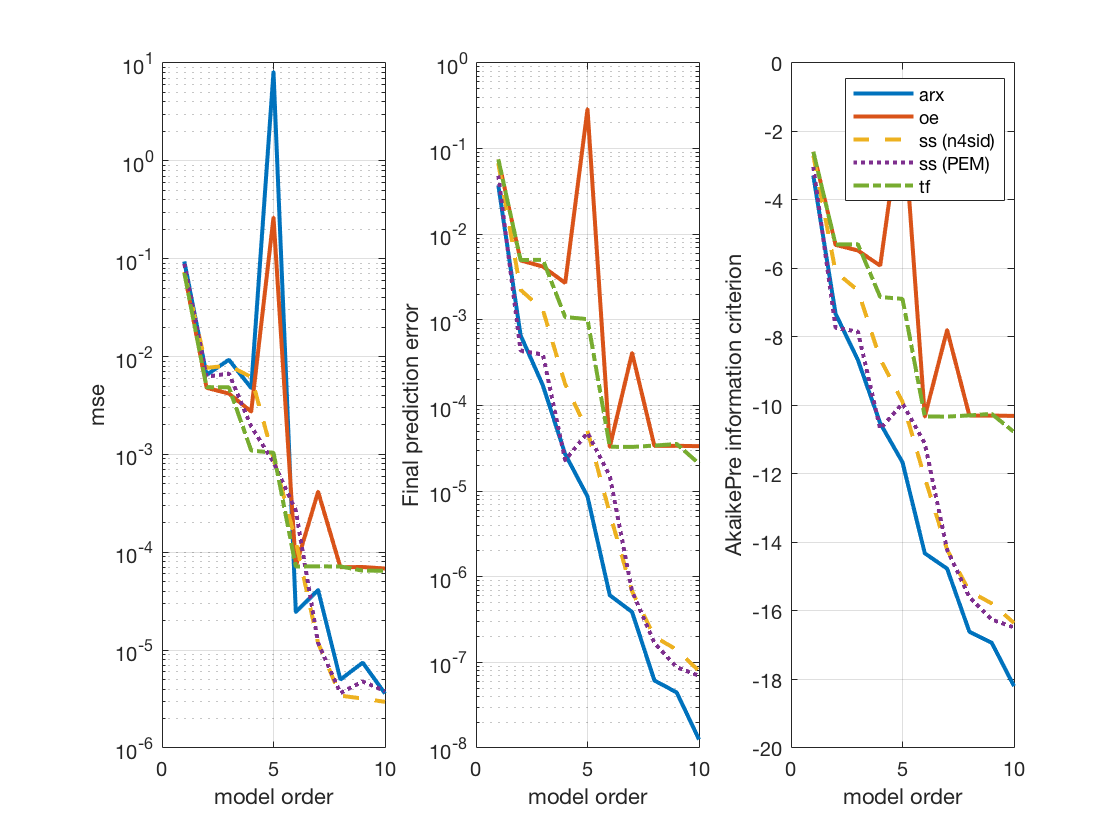


figure;
NameArray = {'LineStyle'};
ValueArray = {'-','-','--',':','-.'}';
subplot(1,3,1); p1 = semilogy(mses,'Linewidth',2); ylabel('mse'); xlabel('model order'); grid on
set(p1,NameArray,ValueArray)
subplot(1,3,2); p3 = semilogy(akaikePre,'Linewidth',2); ylabel('Final prediction error'); xlabel('model order'); grid on
set(p3,NameArray,ValueArray)
subplot(1,3,3); p4 = plot(akaikeIC,'Linewidth',2); ylabel('AkaikePre information criterion'); xlabel('model order'); grid on
set(p4,NameArray,ValueArray)
legend('arx', 'oe', 'ss (n4sid)', 'ss (PEM)', 'tf')


% In discrete-time, a transfer function model has very similar form as the
% OE model, one possible exception is that sometimes by adding feedthrough,
% tf model has parameter b0 in the numerator.

% Due to the high similarity of the training and validation data, it is
% unlikely that overfitting will happen, even we use too many model
% parameters. Thus, we should use the parsimony principle to choose the one
% with fewer free parameters or lower model order among those with similar
% performance.


%%
disp('pzmaps...')

pzmaps...


% pzplots(models, 6)
disp('We can further analysis the suitable number of poles and zeros from the pole/zero plot.')

We can further analysis the suitable number of poles and zeros from the pole/zero plot.


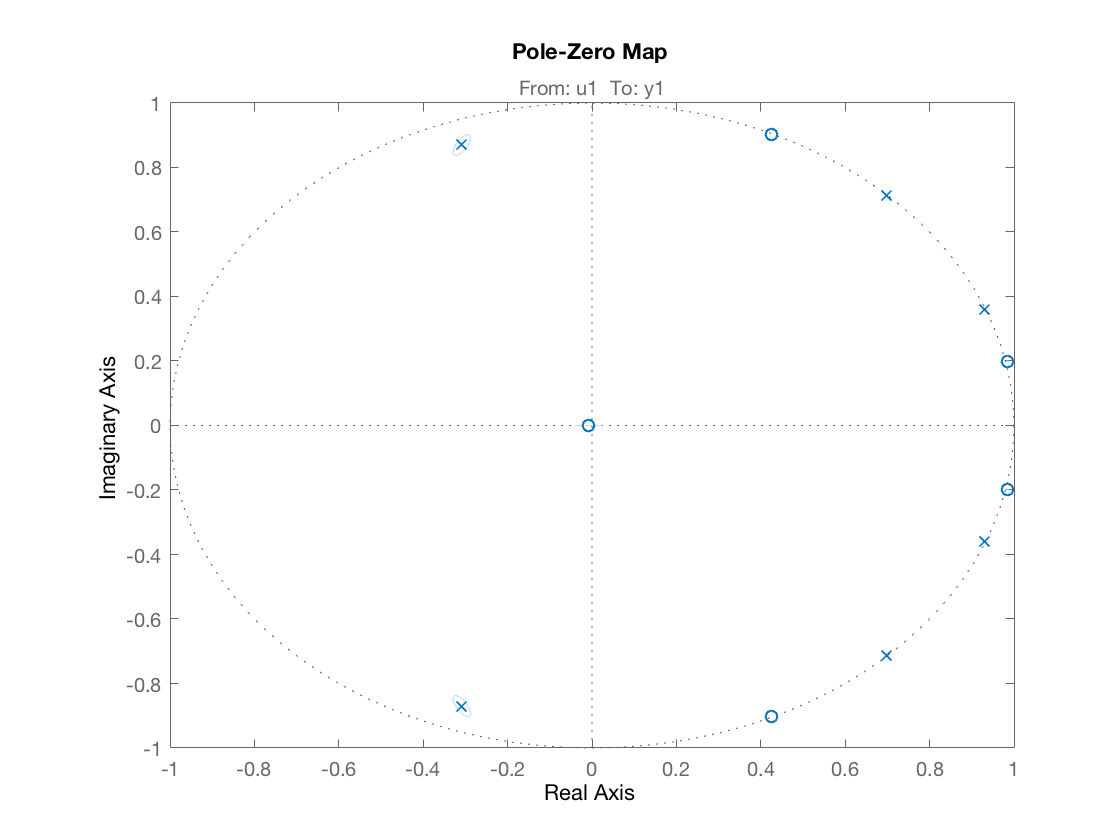


figure
h = iopzplot(models{6,1});
showConfidence(h, 0.95)


disp('We can reduce one parameter from the numerator!')

We can reduce one parameter from the numerator!


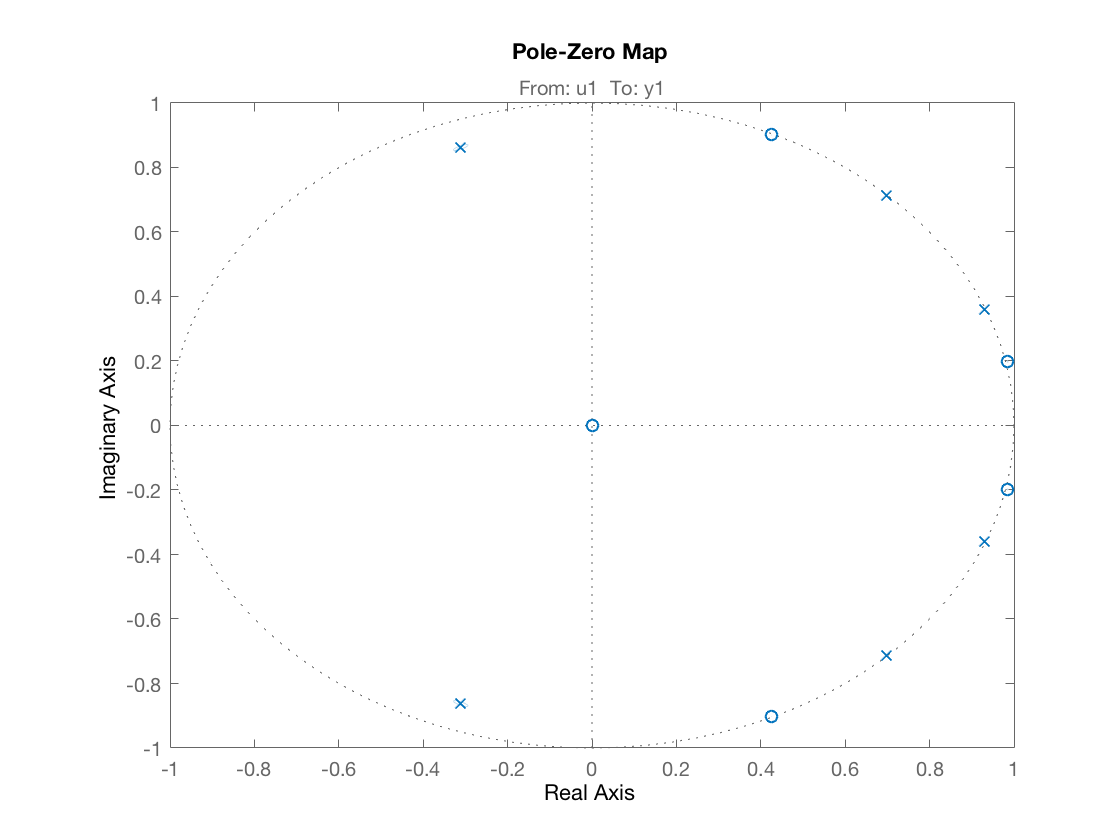

figure
arx65 = arx(zt,[6 5 1]);
h = iopzplot(arx65);
showConfidence(h, 0.95)

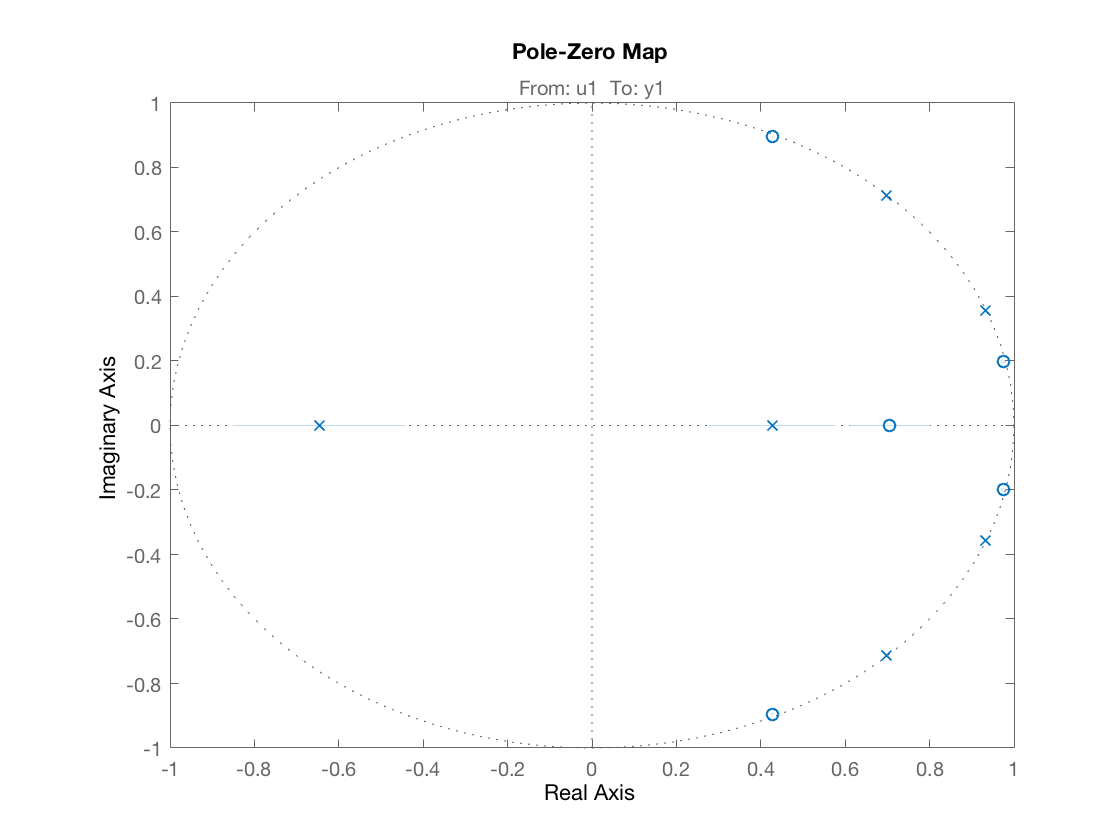


figure
h = iopzplot(models{6,3});
showConfidence(h, 0.95)


%%
% disp('Nyquist plot...')
% % nyquistplots(models, 6)
% 
% figure
% h = nyquistplot(models{6,1});
% showConfidence(h, 0.95)
% 
% figure
% h = nyquistplot(arx65);
% showConfidence(h, 0.95)
% 
% figure
% h = nyquistplot(models{6,3});
% showConfidence(h, 0.95)

%%
disp('Bode plots...')

Bode plots...


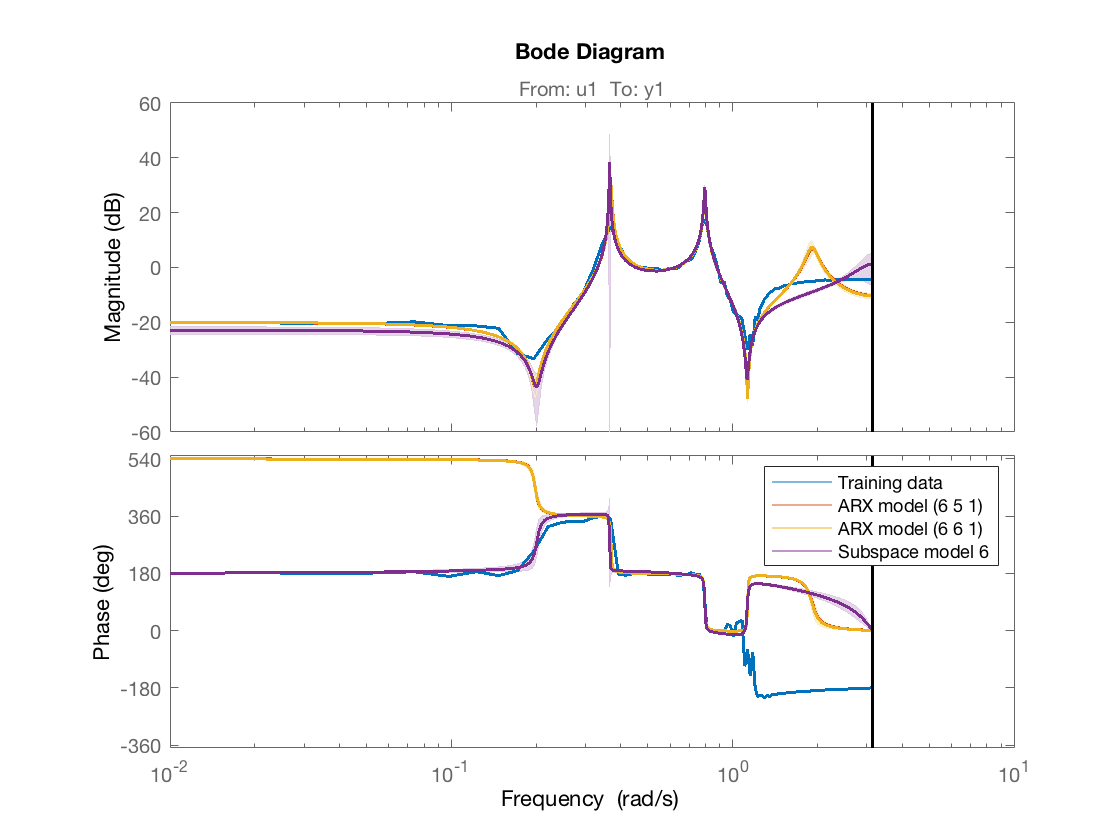

% bode_plots(models, [6, 8], ge_t)

figure; hold on
bode(ge_t);
h = bodeplot(arx65);
showConfidence(h, 0.95);
h = bodeplot(models{6,1});
showConfidence(h, 0.95);
h = bodeplot(models{6,3});
showConfidence(h, 0.95);
legend('Training data','ARX model (6 5 1)','ARX model (6 6 1)','Subspace model 6')
set(findall(gcf,'type','line'),'linewidth',1.5)


% Here, we can see that the gain margin when phase is at -180 degree, around the Nyquist frequency
% varies a lot compared to the empirical transfer function update, which is
% almost constant. This implies that we probability need some further data
% preprocessing step to filter out the high-frequency component of the
% data.

%%
disp('Simulations')

Simulations


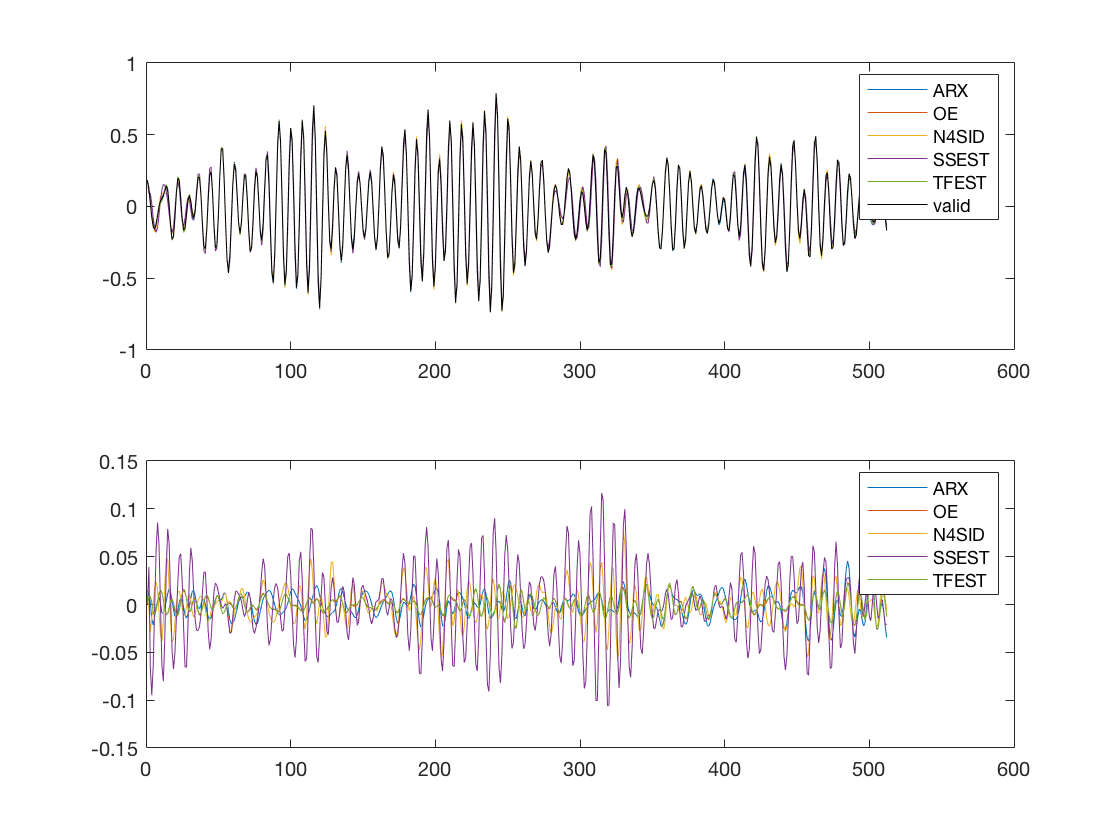

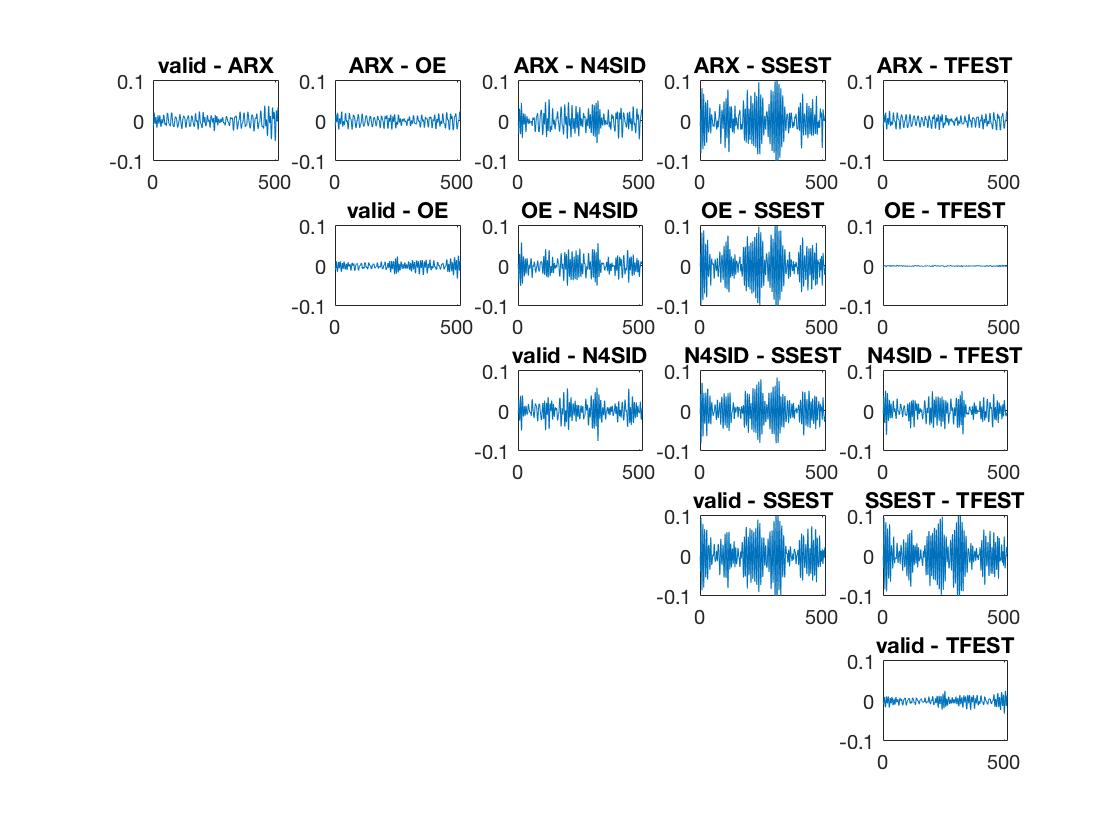

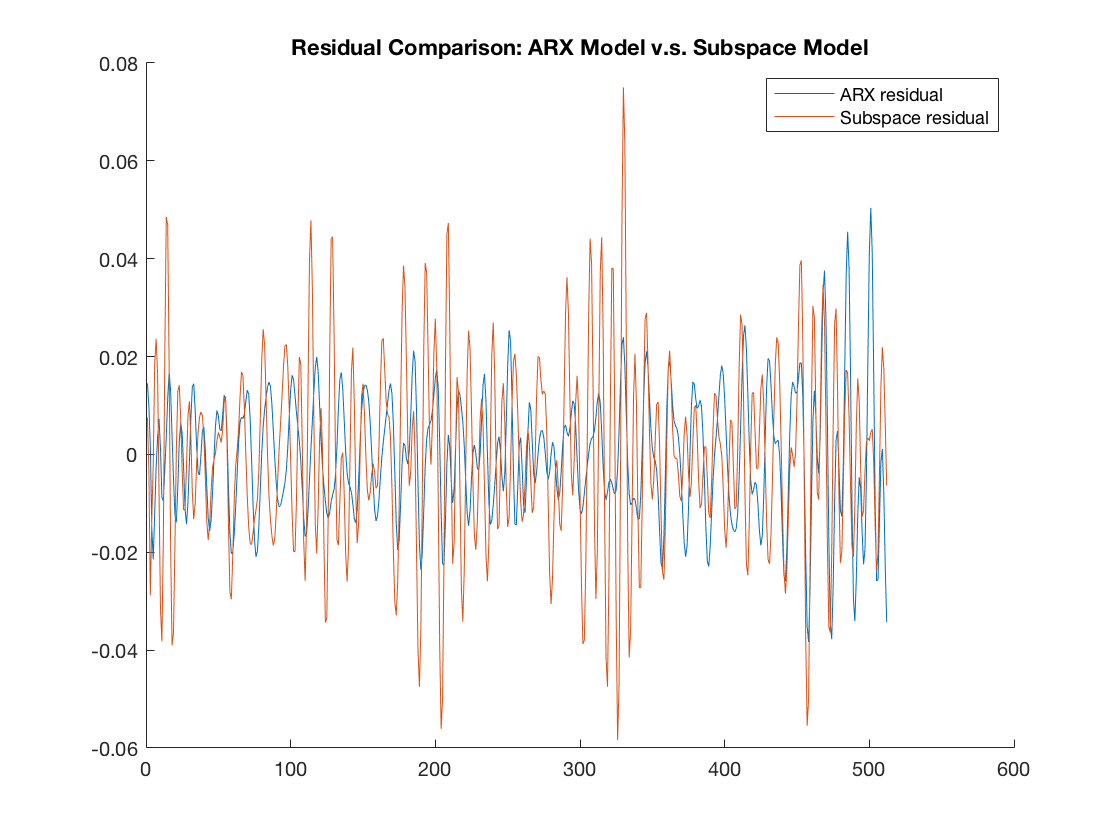

model_order = 6;
peplot(models, model_order, zv, inf)


disp('Predicions')

Predicions


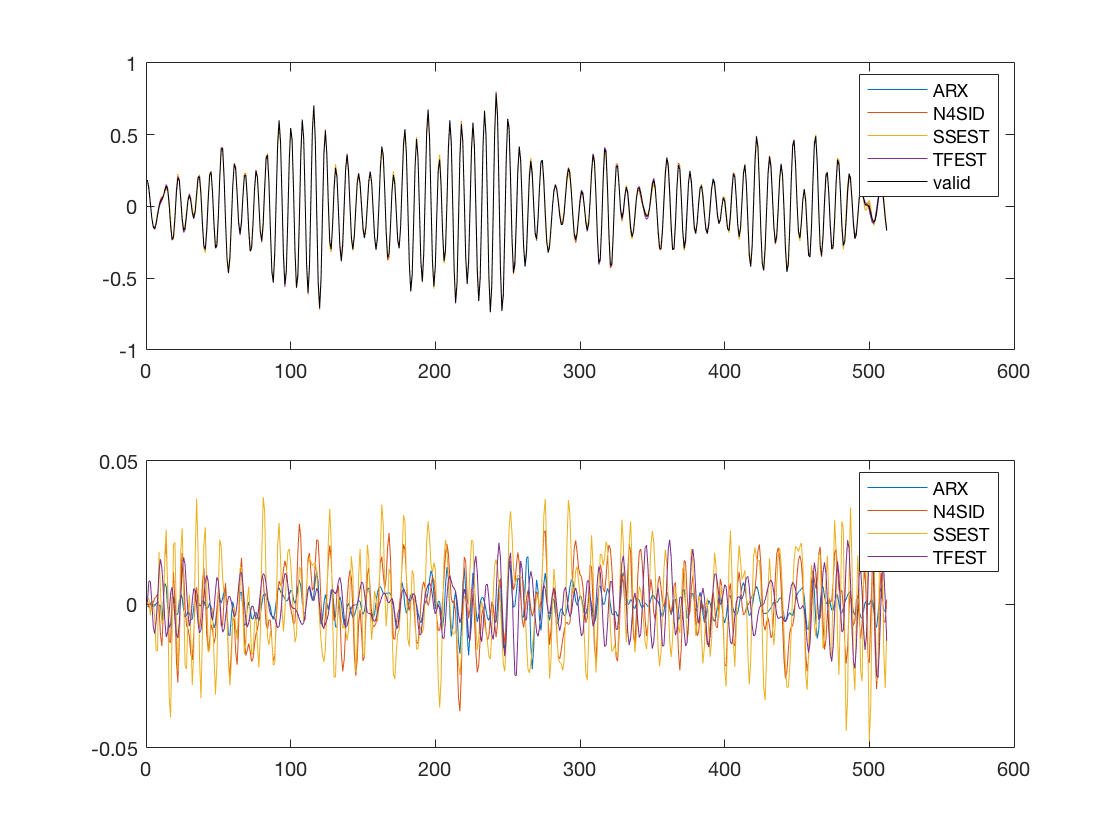

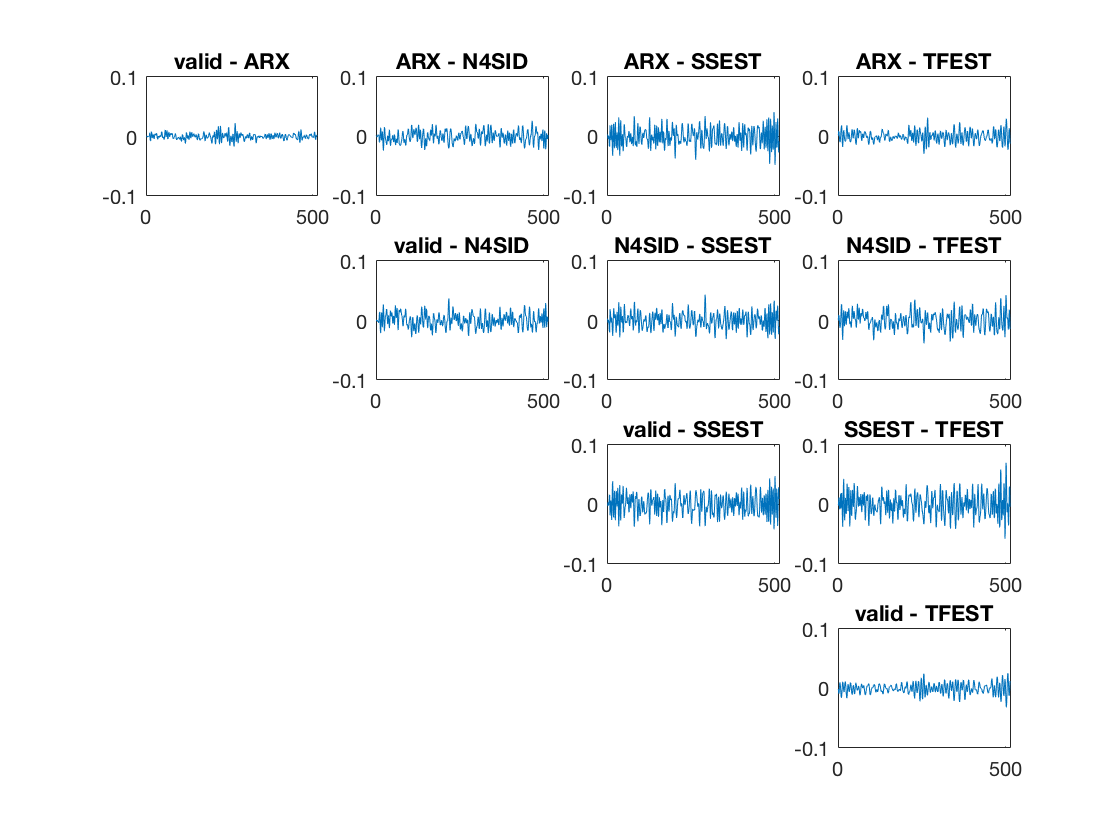

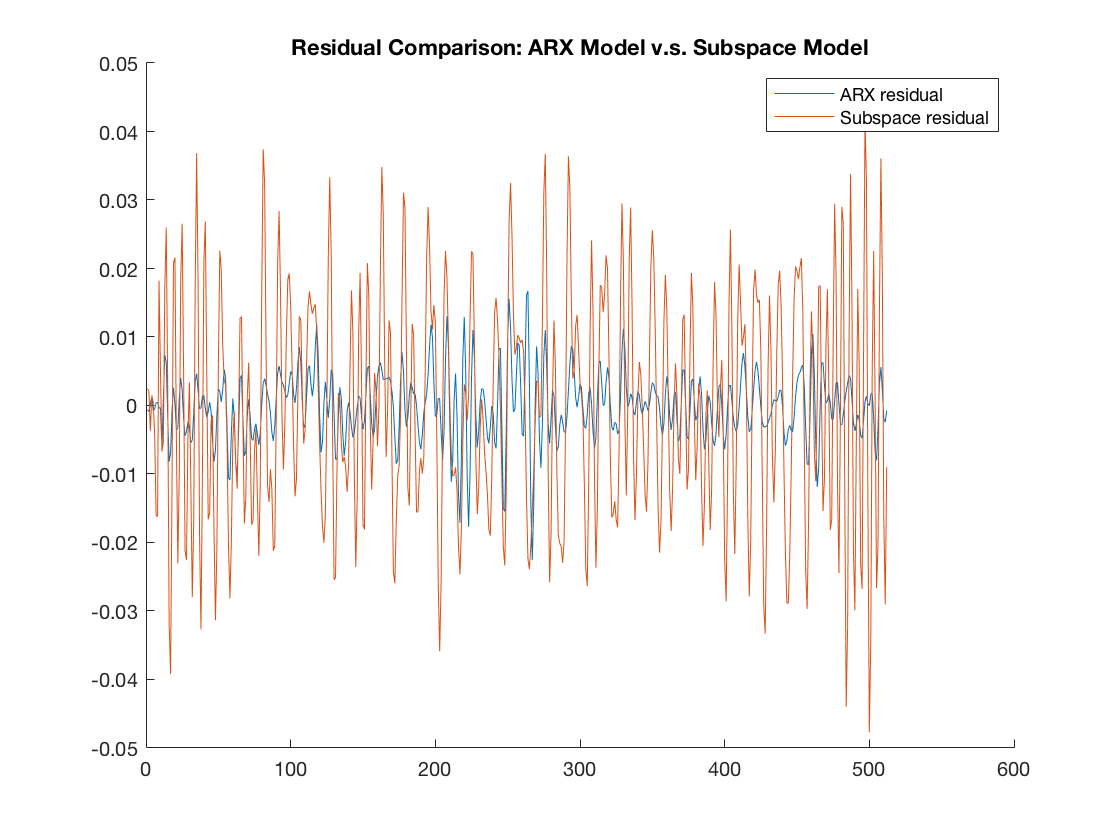

model_order = 6;
k = 5;
models_idx = cell2mat(cellfun(@(x) ~isequal(x,@oe), model_handles, 'UniformOutput', false));
peplot(models(:,models_idx), model_order, zv, k)


%%
disp('Residual Analysis')

Residual Analysis


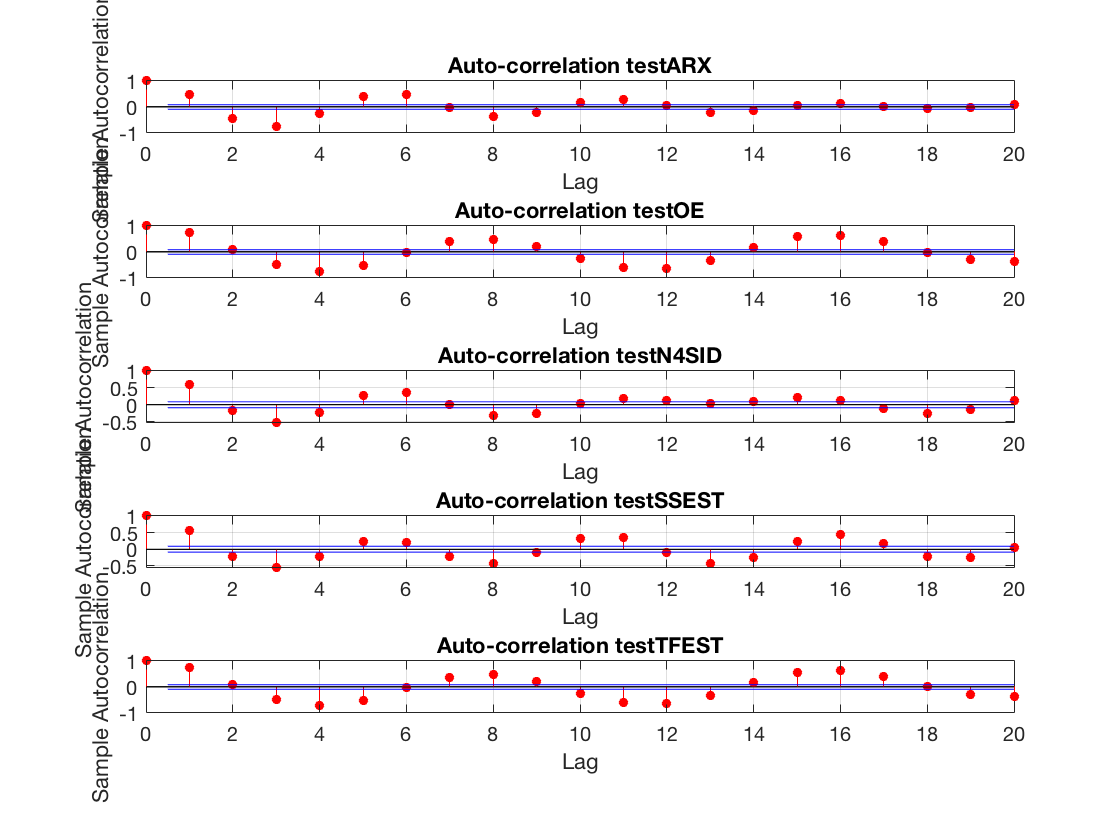

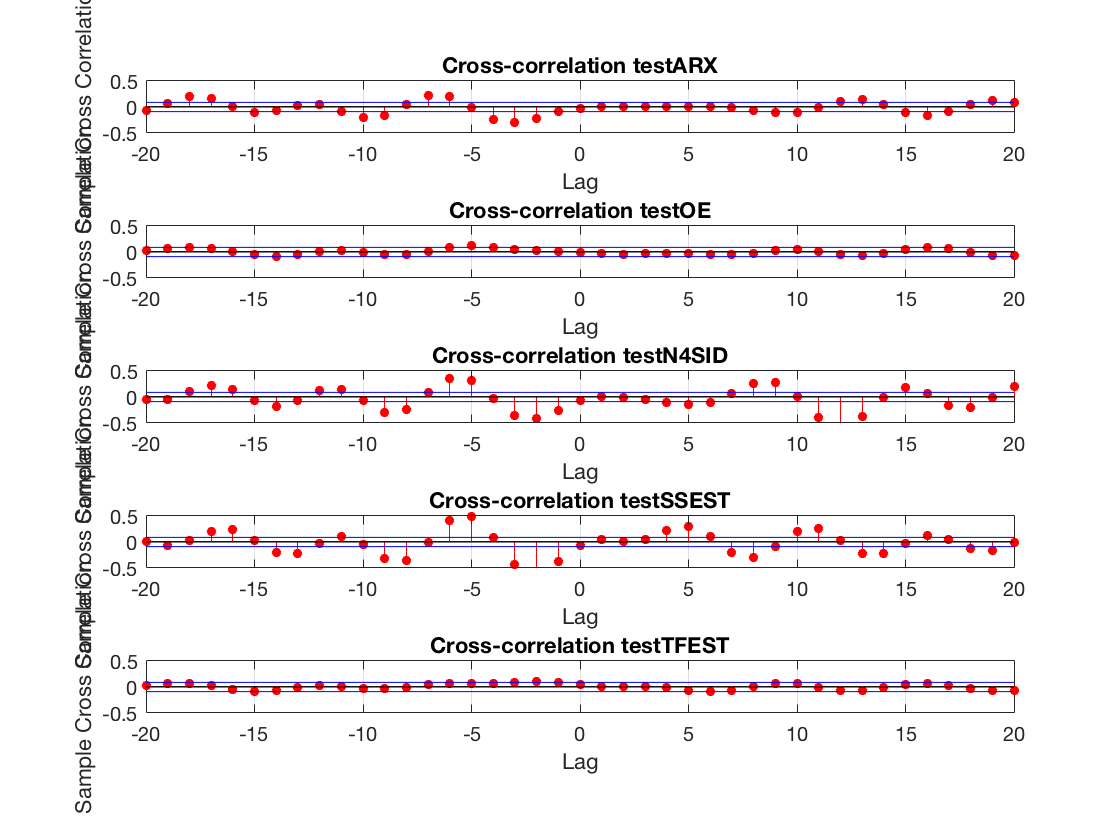

model_order = 6;
residualAnalysis_plot(models, model_order, zt, 1) % Estimation data


% Overall, ARX model is the one that best fits the data.

%%
disp('Nonlinear Identification')

Nonlinear Identification


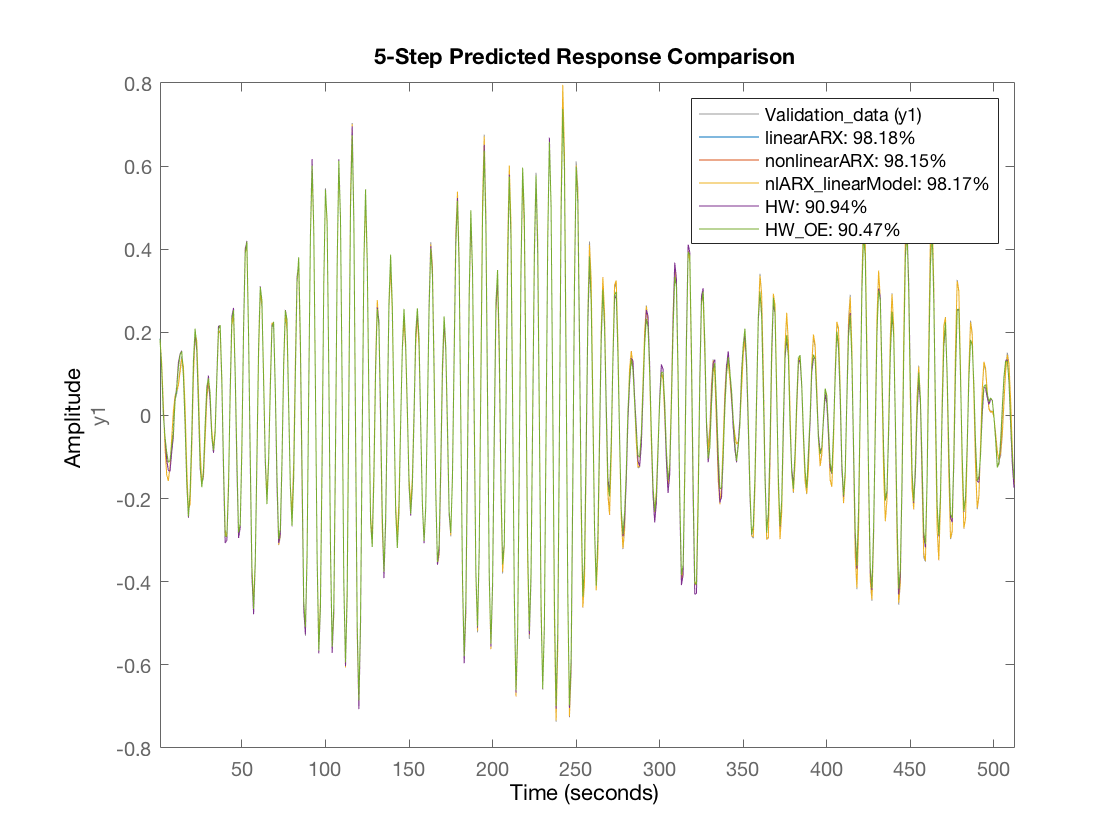

nonlinearARX = nlarx(zt,[6 5 1]);
% nonlinearARX_Refined = nlarx(zt,nonlinearARX);
linearARX = arx(zt,[6 5 1]);
nlARX_linearModel = nlarx(zt,linearARX);
HW = nlhw(zt,[6 5 1]);
% HW_Refined = nlhw(zt,HW);
linearOE = oe(zt,[6 5 1]);
HW_OE = nlhw(zt,linearOE);

Validation_data = zv;

figure
compare(Validation_data, linearARX, nonlinearARX, nlARX_linearModel,HW, HW_OE, 5);

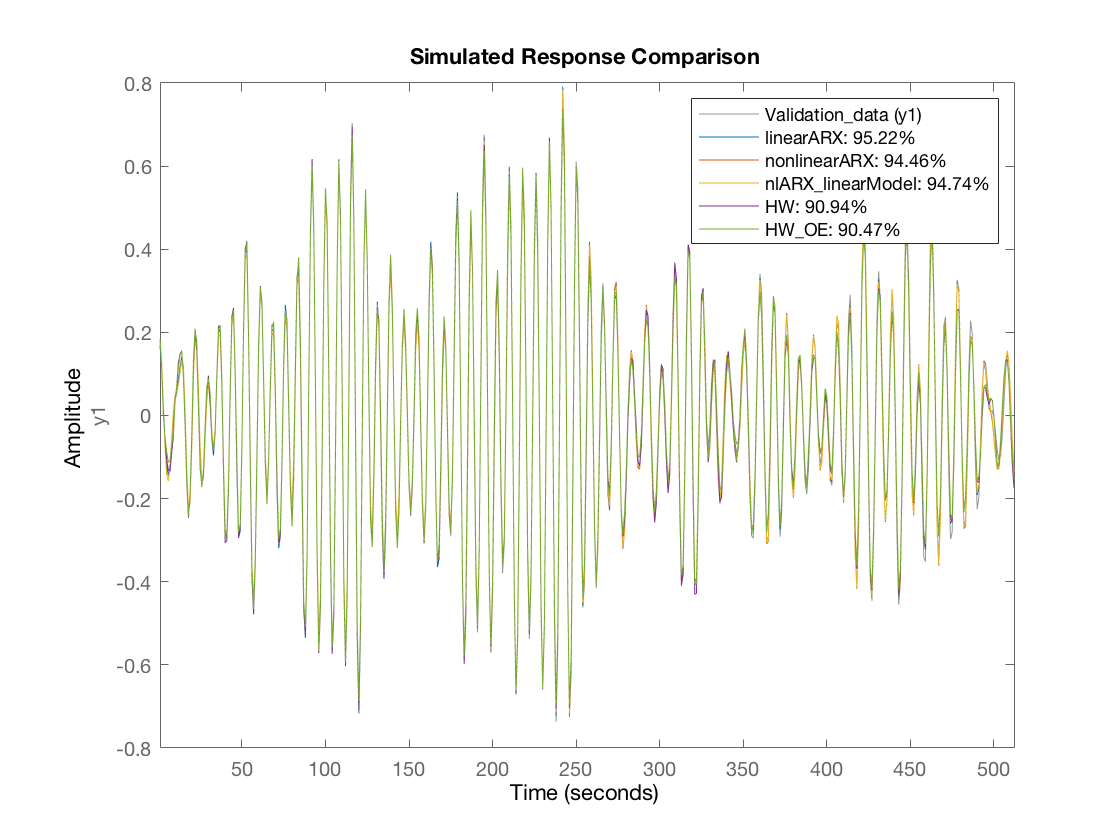

figure
compare(Validation_data, linearARX, nonlinearARX, nlARX_linearModel,HW, HW_OE, inf);


%%
% ARX
% disp('Fitting ARX models')
% Opt = arxOptions;
% k = 10;
% arxL = arx(zt, [4 4 1], Opt);
% arxM = arx(zt,[6 6 1], Opt);
% arxH = arx(zt,[8 8 1], Opt);
% predL = predict(arxL, zv, k);
% predM = predict(arxM, zv, k);
% predH = predict(arxH, zv, k);
% mseH = immse(yv, predH.y); mseM = immse(yv, predM.y); mseL = immse(yv, predL.y);
% figure
% plot(yv,'LineWidth',1.5); hold on; plot(predL.y); plot(predM.y); plot(predH.y);
% title('Trained ARX models')
% legend('y', sprintf('lower order (%.3e)', mseL),...
%     sprintf('medium order (%.3e)', mseM), ...
%     sprintf('high order (%.3e)', mseH));
% pause
% 
% disp('Bode plots of the models')
% figure
% bode(arxL, arxM, arxH)
% legend('lower order','medium order', 'high order');
% 
% pause
% 
% disp('The low order model is to simple')
% figure
% plot(yv,'LineWidth',1.5); hold on; plot(predM.y); plot(predH.y);
% title('Trained ARX models')
% legend('y', sprintf('medium order (%.3e)', mseM), ...
%     sprintf('high order (%.3e)', mseH));
% disp('The training and validation data include very little variation which makes the model estimation prone to overfit without showing in the mse (variance part)!')
% disp('We need to be careful that the model is not overfitting')
% pause
% 
% % State space model estimation 
% disp('Estimating State Space models')
%                       
% Options = n4sidOptions;                             
% Options.Display = 'on';
% ss1 = n4sid(zv, 8, Options);
% ss2 = n4sid(zv, 10, 'Form', 'canonical', Options);
% pred_ss1 = predict(ss1, zv, k);
% pred_ss2 = predict(ss2, zv, k);
% mse_ss1 = immse(yv, pred_ss1.y); mse_ss2 = immse(yv, pred_ss2.y);
% figure
% plot(yv,'LineWidth',1.5); hold on; plot(pred_ss1.y); plot(pred_ss2.y);
% title('Trained State Space models')
% legend('y', sprintf('Free (mse=%.3e)', mse_ss1), ...
%     sprintf('OC (mse=%.3e)', mse_ss2));
% 
% pause
% 
% 
% disp('Comparing different model structures')
% arx_opt = arxH; ss_opt = ss2;
% yp_arx = predict(arx_opt, zv, 1);
% yp_ss = predict(ss_opt, zv, 1);
% mse_arx = immse(yv, yp_arx.y); mse_ss = immse(yv, yp_ss.y);
% figure
% plot(yv,'LineWidth',1.5); hold on; plot(yp_arx.y); plot(yp_ss.y);
% title('Trained models')
% legend('y', sprintf('ARX (mse=%.3e)', mse_arx), ...
%     sprintf('SS (mse=%.3e)', mse_ss));
% pause
% 
% figure; pzmap(arx_opt);
% figure; pzmap(ss_opt);

%% Functions
% auto- and cross-correlation


function correlations(u_in, y_in)
    figure
    cv = 2/sqrt(length(u_in)); %critival value, using normal assumption
    subplot(2,2,1); autocorr(u_in, 'NumLags', 50); title('autocorr(u(t))')
    subplot(2,2,3); [r_yu, lags] = xcorr(y_in, u_in, 50, 'coeff'); stem(lags, r_yu, '.')
    hold on; plot(lags, cv*ones(size(lags)), 'k', lags, -cv*ones(size(lags)), 'k');
    title('xcorr(y(t), u(t))')
    subplot(2,2,4); autocorr(y_in, 'NumLags', 50); title('autocorr(y(t))')
end


function [trained_models, mses, freeParams, akaikePre, akaikeIC] = modelOrderVsFreeParams(models, zt, zv, n, k)
    num_models = length(models);
    mses = zeros(n, num_models);
    akaikePre = zeros(n, num_models);
    akaikeIC = zeros(n, num_models);
    freeParams = zeros(n, num_models);
    trained_models = cell(n, num_models);
    for ni=1:n
        for mi = 1:num_models
            model = models{mi};
            mfun = functions(model);
            fprintf('Model order %d for %s\n', ni, mfun.function);
            switch mfun.function
                case 'arx'
                    Opt = arxOptions;
                    ns = [ni ni 1];
                    opt_fun = @() model(zt, ns, Opt);
                case 'oe'
                    Opt = oeOptions;
                    ns = [ni ni 1];
                    Opt.Focus = 'simulation';
                    opt_fun = @() model(zt, ns, Opt);
                case 'n4sid'
                    Opt = n4sidOptions;       
%                     Opt.Display = 'on';
                    ns = ni;
                    opt_fun = @() model(zt, ns, 'Form', 'canonical', Opt);
                case 'ssest'
                    Opt = ssestOptions;       
%                     Opt.Display = 'on';     
                    ns = ni;
                    opt_fun = @() model(zt, ns, 'Form', 'canonical', Opt);
                case 'tfest'
                    Opt = tfestOptions;                   
%                     Opt.Display = 'on';                   
                    Opt.WeightingFilter = [];
                    ns = ni;
                    opt_fun = @() model(zt, ns, Opt, 'Ts', 1);
                otherwise
            end
            
            m = opt_fun();
            trained_models{ni, mi} = m;
            freeParams(ni, mi) = sum(m.Report.Parameters.Free);
            yp = predict(m, zv, k); % k-step prediction
            mse = immse(zv.y, yp.y); 
            mses(ni, mi) = mse;
            akaikePre(ni,mi) = m.Report.Fit.FPE;
            akaikeIC(ni,mi) = m.Report.Fit.nAIC;
        end
    end
end

function bode_plots(models, idxs, ge)
    [nrows, ncols] = size(models);
    rows = 1:nrows;
    for i = 1:ncols
        figure;
        leg = cell(1, length(idxs)+1);
        bode(ge); leg{1,1} = 'train'; hold on;
        for k = 1:length(idxs)
            idx = idxs(k);
            j = rows(idx);
            h = bodeplot(models{j,i});
            showConfidence(h, 0.95);
            leg{1, k+1} = strcat(int2str(idx),' (', models{1,i}.Report.method, ')');
        end
        legend(leg)
        set(findall(gcf,'type','line'),'linewidth',2)
    end
end

function pzplots(models, model_order)
    [nrows, ncols] = size(models);
    rows = 1:nrows;
    M = ceil(sqrt(ncols));
    figure;
    for i = 1:ncols
        subplot(M, ceil(ncols/M), i);
        j = rows(model_order);
        h = iopzplot(models{j,i});
        showConfidence(h, 0.95)
        legend(strcat(int2str(model_order),' (', models{1,i}.Report.method, ')'))
    end
end

function nyquistplots(models, model_order)
    [nrows, ncols] = size(models);
    rows = 1:nrows;
    M = ceil(sqrt(ncols));
    figure;
    for i = 1:ncols
        subplot(M, ceil(ncols/M), i);
        j = rows(model_order);
        h = nyquistplot(models{j,i});
%         showConfidence(h, 0.95)
        legend(strcat(int2str(model_order),' (', models{1,i}.Report.method, ')'))
    end
end

function peplot(models, model_order, zv, k)
    [nrows, ncols] = size(models);
    rows = 1:nrows;
    figure;
    leg1 = cell(1, ncols+1);
    leg2 = cell(1, ncols);
    P = zeros(ncols, length(zv.y));
    e = zeros(ncols, length(zv.y));
    for i = 1:ncols
        j = rows(model_order);
        pred = predict(models{j,i}, zv, k);
        P(i, :) = pred.y;
        e(i,:) = zv.y - pred.y;
        subplot(2,1,1); plot(pred.y); hold on;
        subplot(2,1,2); plot(e(i,:)); hold on;
        leg1{1, i} = models{1,i}.Report.method;
        leg2{1, i} = models{1,i}.Report.method;
    end
    subplot(2,1,1); plot(zv.y, 'k'); hold on; leg1{1,end} = 'valid';
    subplot(2,1,1); legend(leg1);
    subplot(2,1,2); legend(leg2);
    figure
    for i = 1:ncols
        for j = i:ncols
            subplot(ncols, ncols, (i-1)*ncols+j)
            if i == j
                plot(P(i,:) - zv.y')
                title(sprintf('valid - %s',models{1,i}.Report.method))
            else
                plot(P(i,:)-P(j,:))
                title(sprintf('%s - %s',models{1,i}.Report.method,models{1,j}.Report.method))
            end
        ylim([-0.1 0.1])    
            
        end
    end
    figure; hold on
    plot(e(1,:)); plot(e(3,:))
    title('Residual Comparison: ARX Model v.s. Subspace Model')
    legend('ARX residual','Subspace residual')
end

function residualAnalysis_plot(models, model_order, zv, k)
    [nrows, ncols] = size(models);
    rows = 1:nrows;
    figure;
    P = zeros(ncols, length(zv.y));
    for i = 1:ncols
        j = rows(model_order);
        pred = predict(models{j,i}, zv, k);
        P(i, :) = pred.y;
        e = zv.y - pred.y;
        subplot(ncols,1,i); autocorr(e); title(strcat('Auto-correlation test ',models{1,i}.Report.method));
    end
    figure;
    for i = 1:ncols
        j = rows(model_order);
        pred = predict(models{j,i}, zv, k);
        P(i, :) = pred.y;
        e = zv.y - pred.y;
        subplot(ncols,1,i); crosscorr(zv.u,e); ylim([-0.5,0.5]); title(strcat('Cross-correlation test ',models{1,i}.Report.method));
    end
end

